**1. Considere a informação relativa a um exemplo simples de sentiment analysis – retirado do capítulo**

**Naive Bayes and Sentiment Classification referido acima – apresentada na Tabela:**

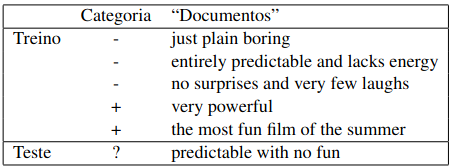

**(a) **Comece por criar um vetor com a lista de palavras únicas no conjunto de treino. Deve ser criado de forma automática, numa função, tendo por entrada um cell array com o conteúdo dos documentos.

Documentos = {'just plain boring', 'entirely predictable and lacks energy', 'no surprises and very few laughs', 'very powerful', 'the most fun film of the summer'};

PalavrasUnicas = unique(strsplit(strjoin(Documentos)))

PalavrasUnicas = 1×20 cell array
    {'and'}    {'boring'}    {'energy'}    {'entirely'}    {'few'}    {'film'}    {'fun'}    {'just'}    {'lacks'}    {'laughs'}    {'most'}    {'no'}    {'of'}    {'plain'}    {'powerful'}    {'predictable'}    {'summer'}    {'surprises'}    {'the'}    {'very'}


**(b)** Crie uma matriz com informação sobre o número de ocorrências de cada uma das palavras em cada um dos documentos. As linhas devem representar o documento e as colunas a palavra.

numDocs = length(Documentos);
numPalavras = length(PalavrasUnicas);
Matriz = zeros(numDocs, numPalavras);

for i = 1:numDocs
    Palavras = strsplit(Documentos{i});
    for j = 1:numPalavras
        Matriz(i, j) = sum(strcmp(Palavras, PalavrasUnicas{j}));
    end
end

rowNames = "Documento "+ (1:5)';
tabela = array2table(Matriz,'RowNames',rowNames,'VariableNames', PalavrasUnicas)

tabela = 5×20 table
                   and    boring    energy    entirely    few    film    fun    just    lacks    laughs    most    no    of    plain    powerful    predictable    summer    surprises    the    very
                   ___    ______    ______    ________    ___    ____    ___    ____    _____    ______    ____    __    __    _____    ________    ___________    

**(c)** Crie um vetor com informação da categoria correspondente a cada linha da matriz da alínea anterior.

Sugestão: usar ’+’ e ’-’ para representar as categorias.

categorias = {'-', '-', '-', '+', '+'};

ans = 1×5 logical array
   0   0   0   1   1


**(d)** Com base nas variáveis que criou anteriormente, calcule, considerando Laplace (add 1) smoothing:

• P (−) e P (+)

• P (“predictable” |+ ), P (“no” |+ ), P (“fun” |+ )

• P (“predictable” |−) , P (“no” |−) , P (“fun” |−)

• Com base nos valores obtidos anteriormente, determine qual a categoria mais provável para a frase de teste? Sugestão: não considere a palavra “with”.

numPositivos = sum(strcmp(categorias, '+'));
numNegativos = sum(strcmp(categorias, '-'));

ProbPositivo = (numPositivos + 1) / (numDocs + 2);
ProbNegativo = (numNegativos + 1) / (numDocs + 2);

IndexPredictable = find(strcmp(PalavrasUnicas, 'predictable'));
IndexNo = find(strcmp(PalavrasUnicas, 'no'));
IndexFun = find(strcmp(PalavrasUnicas, 'fun'));

predictable_Positivo = sum(Matriz(strcmp(categorias, '+'), IndexPredictable));
predictable_Negativo = sum(Matriz(strcmp(categorias, '-'), IndexPredictable));

no_Positivo = sum(Matriz(strcmp(categorias, '+'), IndexNo));
no_Negativo = sum(Matriz(strcmp(categorias, '-'), IndexNo));

fun_Positivo = sum(Matriz(strcmp(categorias, '+'), IndexFun));
fun_Negativo = sum(Matriz(strcmp(categorias, '-'), IndexFun));

numPalavrasPositivas = sum(sum(Matriz(strcmp(categorias, '+'), :))) + numPalavras;
numPalavrasNegativas = sum(sum(Matriz(strcmp(categorias, '-'), :))) + numPalavras;

Prob_Predictable_SabendoPositivo = (predictable_Positivo + 1) / numPalavrasPositivas

Prob_Predictable_SabendoPositivo = 0.0345

Prob_Predictable_SabendoNegativo = (predictable_Negativo + 1) / numPalavrasNegativas

Prob_Predictable_SabendoNegativo = 0.0588


Prob_No_SabendoPositivo = (no_Positivo + 1) / numPalavrasPositivas

Prob_No_SabendoPositivo = 0.0345

Prob_No_SabendoNegativo = (no_Negativo + 1) / numPalavrasNegativas

Prob_No_SabendoNegativo = 0.0588


Prob_Fun_SabendoPositivo = (fun_Positivo + 1) / numPalavrasPositivas

Prob_Fun_SabendoPositivo = 0.0690

Prob_Fun_SabendoNegativo = (fun_Negativo + 1) / numPalavrasNegativas

Prob_Fun_SabendoNegativo = 0.0294

Frase Teste:

'predictable with no fun'

Probabilidade de ser Positivo = ProbPositivo * Prob_Predictable_SabendoPositivo * Prob_No_SabendoPositivo * Prob_Fun_SabendoPositivo;

Probabilidade de ser Negativo = ProbNegativo * Prob_Predictable_SabendoNegativo * Prob_No_SabendoNegativo * Prob_Fun_SabendoNegativo;

ProbTesteSerPositivo = ProbPositivo * Prob_Predictable_SabendoPositivo * Prob_No_SabendoPositivo * Prob_Fun_SabendoPositivo

ProbTesteSerPositivo = 3.5145e-05

ProbTesteSerNegativo = ProbNegativo * Prob_Predictable_SabendoNegativo * Prob_No_SabendoNegativo * Prob_Fun_SabendoNegativo

ProbTesteSerNegativo = 5.8155e-05


if ProbTesteSerPositivo > ProbTesteSerNegativo
    disp('Frase teste é mais provavel de ser positiva')
else
    disp('Frase teste é mais provavel de ser negativa')
end

Frase teste é mais provavel de ser negativa
